Based on the alongshore momentum balance, test a possible relationship between the acceleration of the alongshore flow and the alongshore wind stress at the Del Mar study site.  Use the mode 1 PC to represent the alongshore flow.  The steps are:

1) Load SIO_wind_assignment3.mat and interpolate out NaNs using *interp1*

2) Compute the wind stress using *ra_windstr*

3) Compute EOFs from the Del Mar current and extract the mode 1 PC (A1)

4) Compute the time derivative of A1 using a centered finite difference

5) Remove the means of the alongshore wind stress, Ty and dA1_dt, and normalize by their standard deviations

6) Plot the normalized time series on the same plot

7) Suppress tidal noise in dA1_dt using a running mean (*movmean*) and replot

Load SIO winds

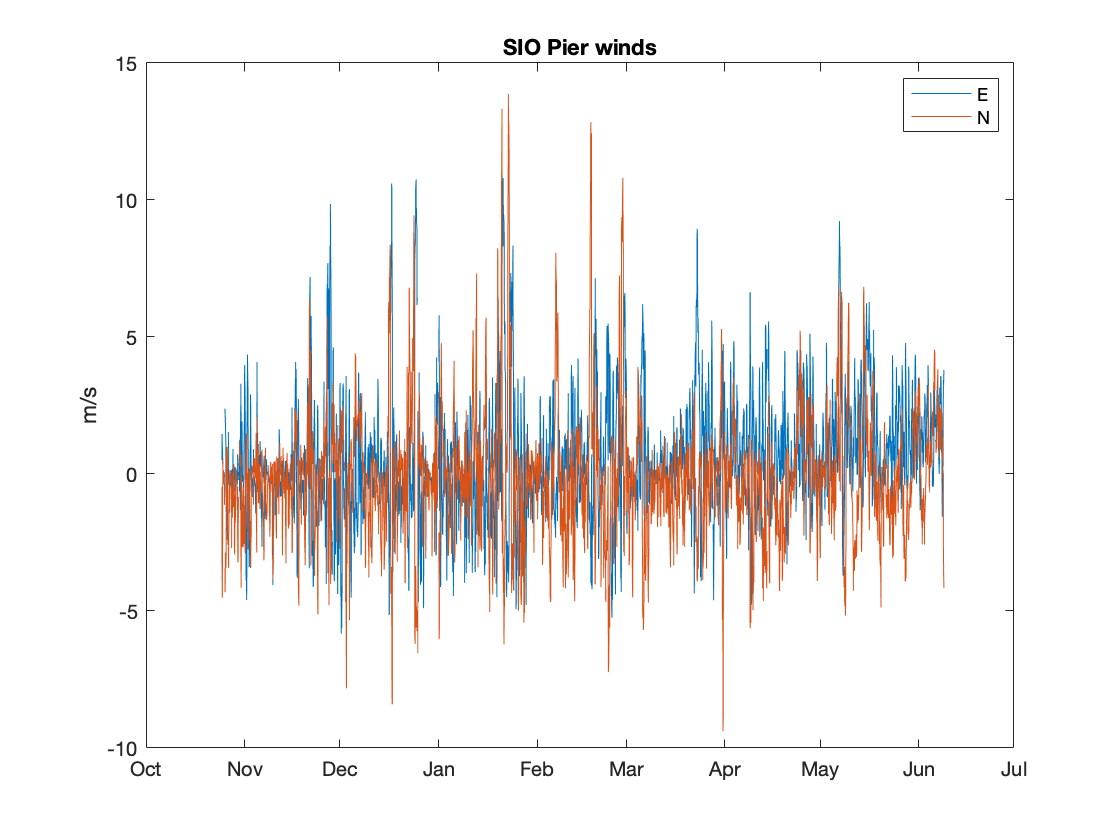

load SIO_wind_assignment3
figure (1)
plot(tw,uw,tw,vw) % expansion fan winds
datetick
ylabel('m/s')
title('SIO Pier winds')
legend('E','N')

Interpolate over gaps using interp1

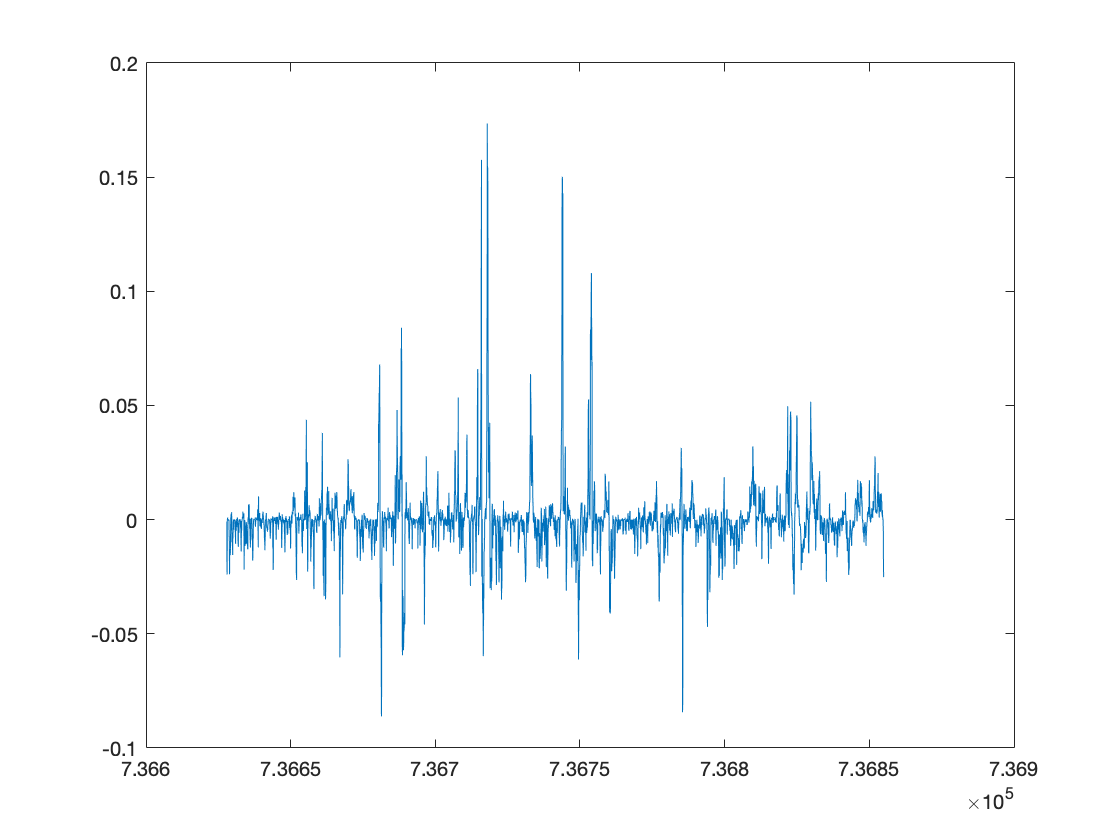

k = find(~isnan(uw.*vw)); % k gives all non nan points
uwi = interp1(tw(k),uw(k),tw); % uwi is uw with interpolated values in place of nans
vwi = interp1(tw(k),vw(k),tw);
% plot(tw,uwi,tw,uw) check to see interp uw vs uw

% get wind stress
[Tx,Ty] = ra_windstr(uwi,vwi);
plot(tw,Ty)

Compute EOFs of the Del Mar currents and extract A1

load DelMar_data
uu = [u;v]';
detrend(uu,0);
[U,S,V] = svd(uu);

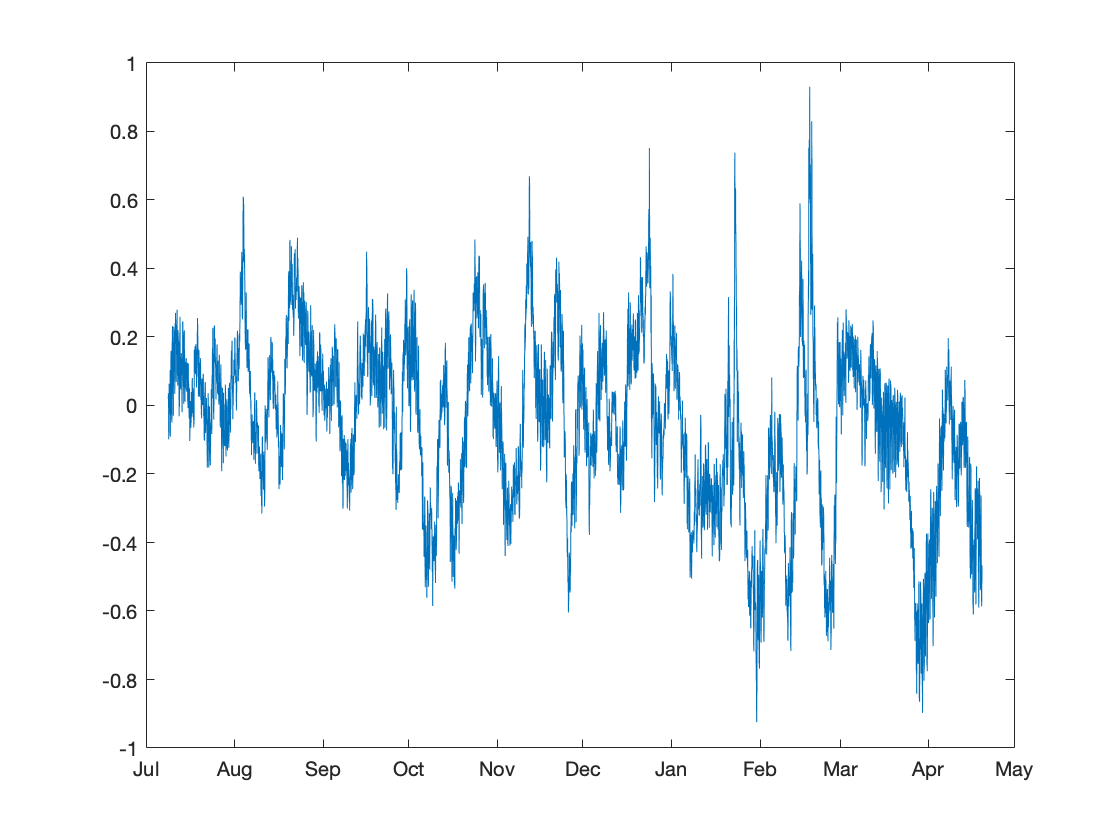

A =  U*S; 

A1 = A(:,1); %1st column is principal component mode 1
% A is the principal component and temporal expansion (same thing in this
% case)
plot(t,A1) % t and A1 has same dimension
datetick

Compute dA1/dt, a proxy for the acceleration of the alongshore current, use a centered finite difference

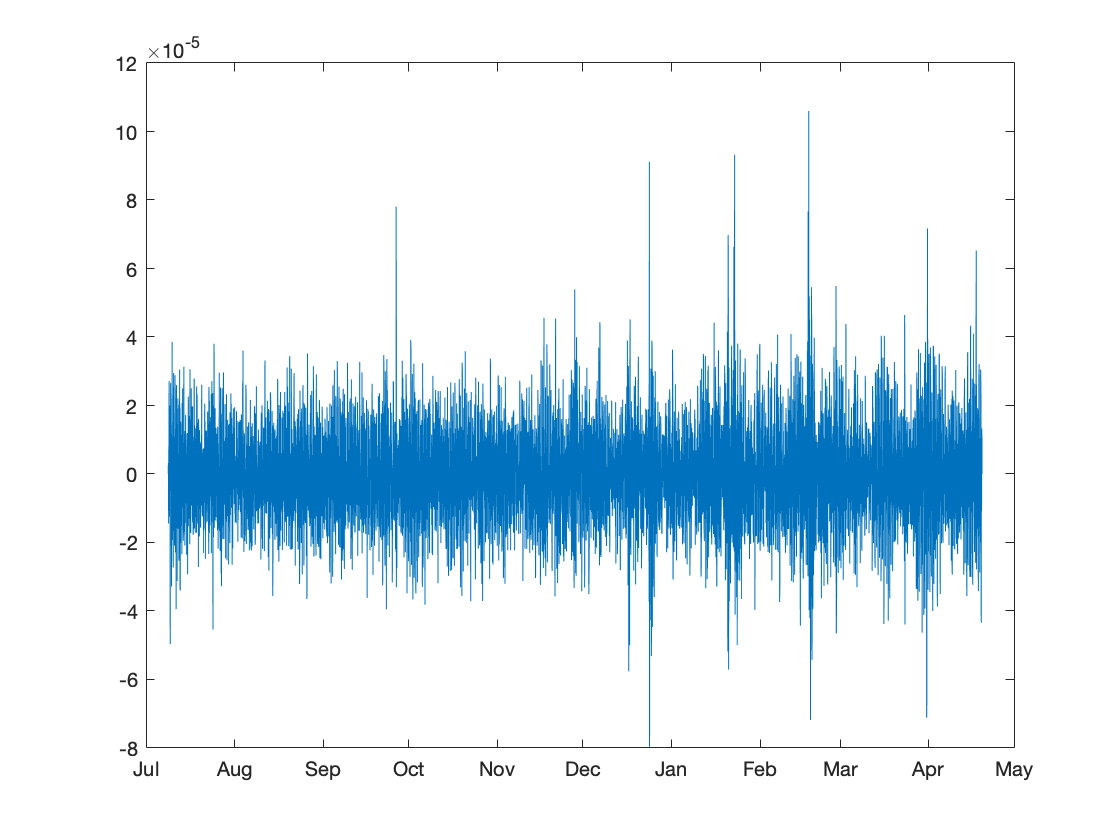

dA1_dt = (A1(3:end)-A1(1:end-2))/(2*30*60);
dA1_dt = [0;dA1_dt;0];
plot(t,dA1_dt)
datetick

Remove means from Ty and dA1_dt and normalize by standard deviations

Tyd = detrend(Ty,0)/std(Ty);
dA1_dtd = detrend(dA1_dt,0)/std(dA1_dt);

Overplot time series

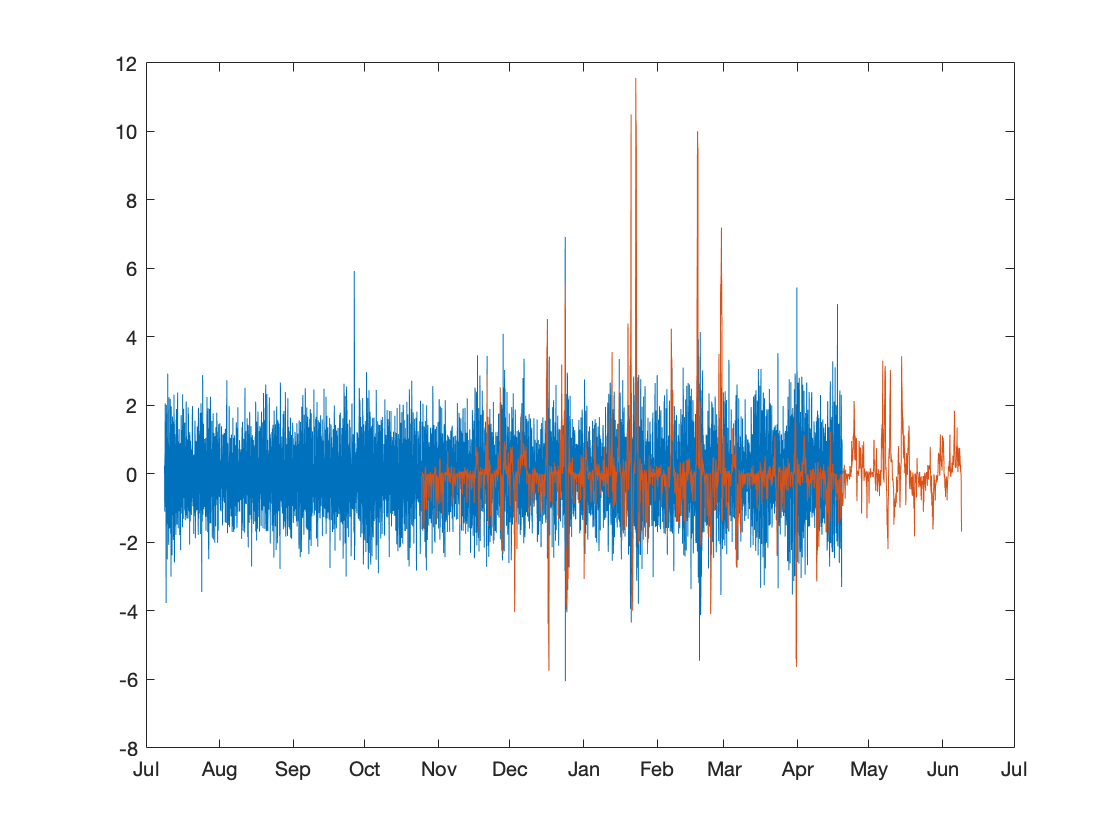

plot(t,dA1_dtd,tw,Tyd)
datetick

Apply a running mean to dA1_dt to suppress tidal variability and replot

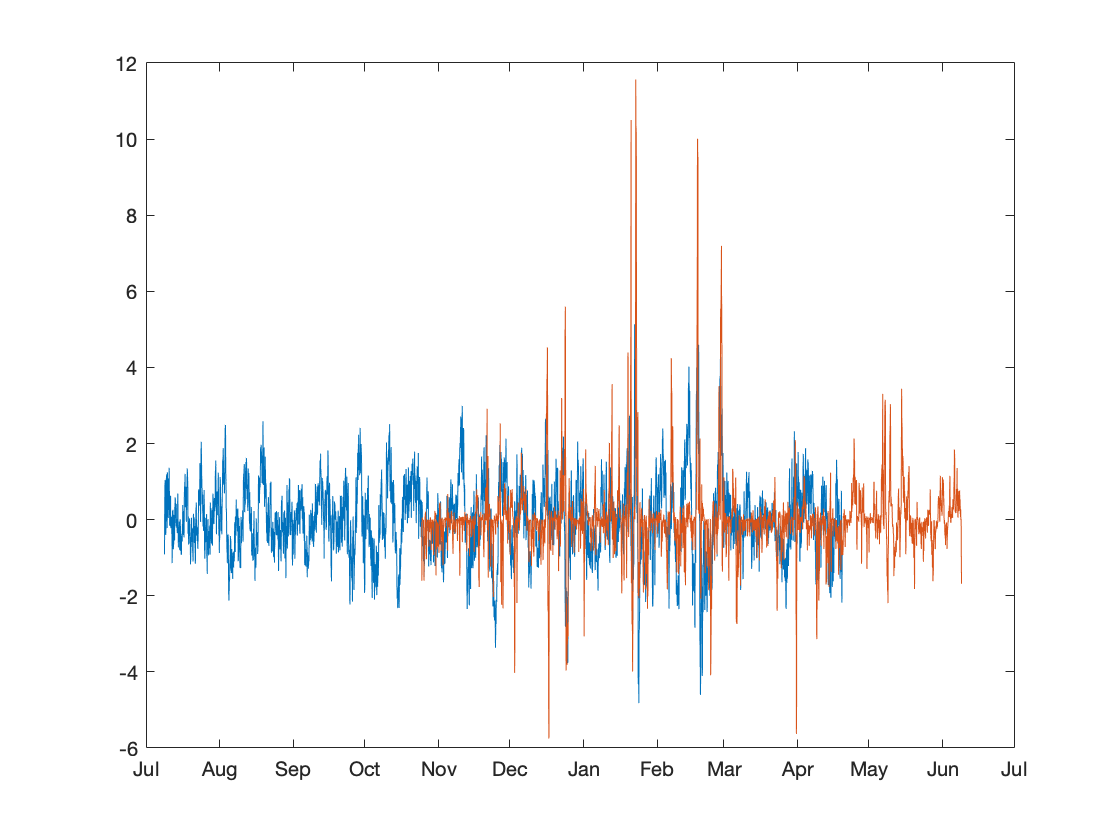

dA1_dt_rm = movmean(dA1_dtd,36*2); % 36 hours and 2?  
plot(t,dA1_dt_rm/std(dA1_dt_rm),tw,Tyd)
datetick

% strong wind peak usually responds to strong current peak, we also want to
% get rid of tidal because it influence current